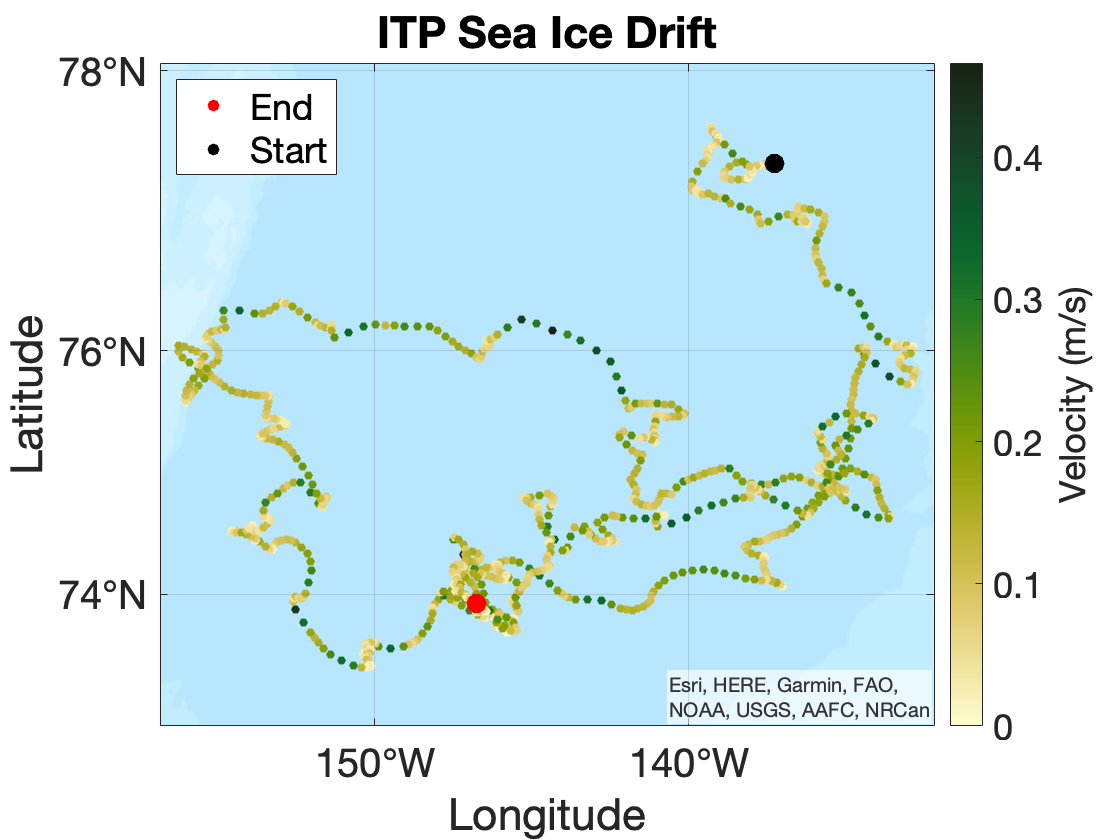

clear
load('itp121_data.mat')
load('derived_variables.mat')
SA = abs_sal;
CT = cons_temp;
%ice sea drift

%time differences
time_diff = diff(time) ; 
distance = gsw_distance(longitude,latitude) ; 
%days to seconds 
time_diff_sec = time_diff .* 86400 ; 

%velcity m/s
vel = distance./time_diff_sec ; 

%new time scale of midpoints
lat_midpoints1 = conv(latitude, ones(2,1), 'valid') / 2 ;
% lat_midpoints2 = conv(latitude, [0.5 0.5], 'valid')
% test = lat_midpoints1 == lat_midpoints2
% i = find(test == 0)
lon_midpoints1 = conv(longitude, ones(2,1), 'valid') / 2 ; 

time_midpoints = conv(time, ones(2,1), 'valid') / 2 ; 

%plot the data
figure(3)
clf
geoscatter(lat_midpoints1,lon_midpoints1,20,vel,"filled") 
cmocean('speed')
c = colorbar; 
c.Label.String = 'Velocity (m/s)';
caxis([min(vel) max(vel)]);
title("ITP Sea Ice Drift")
set(gca,'FontSize',20)
geobasemap topographic
hold on
geoscatter(latitude(end),longitude(end),100,'red','filled')
geoscatter(latitude(1),longitude(1),100,'black','filled')
hold off
legend('','End','Start',"Location","northwest")

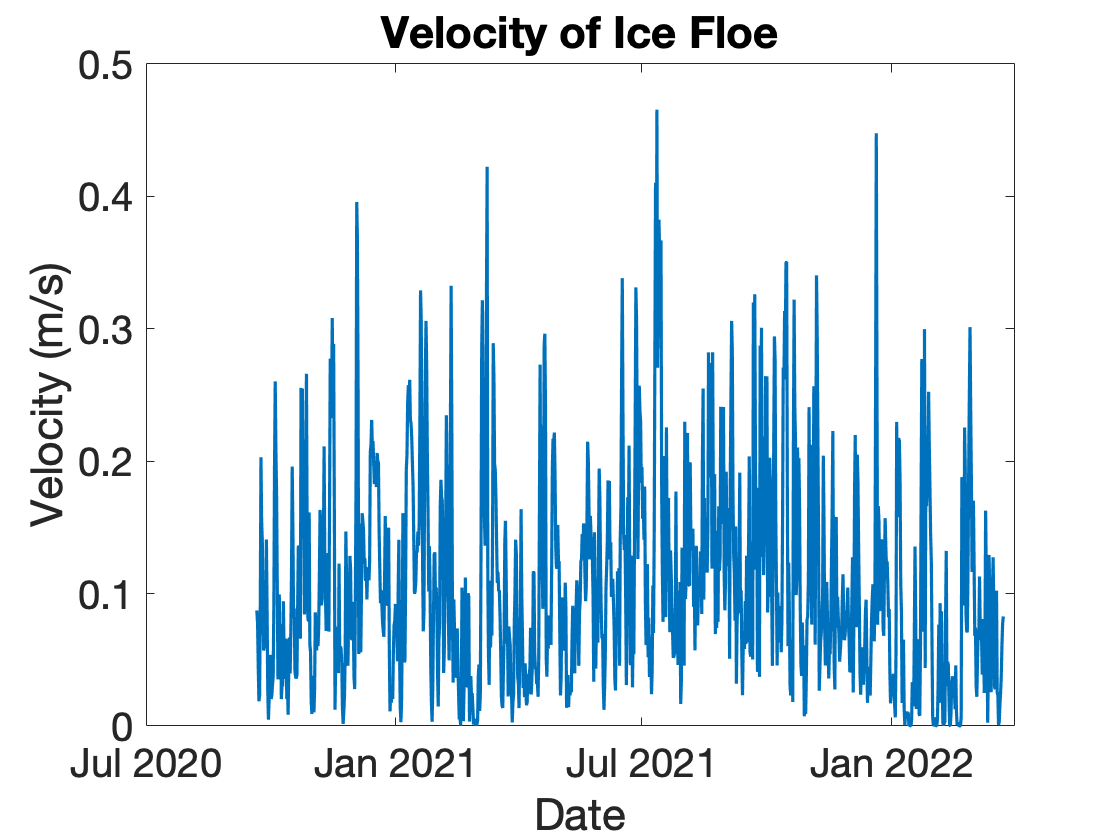


figure(3)
clf
plot(datetime(time_midpoints,'ConvertFrom','datenum'),vel,'LineWidth',1.6)
xlabel('Date')
ylabel('Velocity (m/s)')
title('Velocity of Ice Floe')
set(gca,'FontSize',20)

figure(4)
clf
yyaxis left
plot(datetime(time_midpoints,'ConvertFrom','datenum'),vel,'LineWidth',1.6)
xlabel('Date')
ylabel('Velocity (m/s)')
title('Velocity And Temperature of Ice Floe')
%sst
yyaxis right
UpperLayerTemp = mean(CT(1:14,:),'omitnan')

UpperLayerTemp =    -1.3332   -1.3416   -1.3114   -1.3057   -1.3361   -1.3183   -1.2945   -1.2601   -1.0407   -1.3164   -1.2858   -1.3281   -1.3281   -1.2945   -1.2585   -1.3858   -1.3946   -1.4165   -1.4294   -1.3980   -1.4218   -1.4133   -1.4352   -1.3768   -1.4001   -1.4106   -1.3705   -1.3949       NaN   -1.3219   -1.2963   -1.4741   -1.4771   -1.4566   -1.4775   -1.3385   -1.3913   -1.4103   -1.4294   -1.4004   -1.3351   -1.3559   -1.3089   -1.4173   -1.4030   -1.3996   -1.3780   -1.3544   -1.3599   -1.3563


plot(datetime(time,'ConvertFrom','datenum'),UpperLayerTemp,'LineWidth',1.6)
y = ylabel('Upper 30 M Average Conservative Temperature °C')

y =   Text (Upper 30 M Average Conservative Temperature °C) with properties:

                 String: 'Upper 30 M Average Conservative Temperature °C'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.8500 0.3250 0.0980]
    HorizontalAlignment: 'center'
               Position: [594.8088 -1.1500 -1]
                  Units: 'data'

  Show all properties


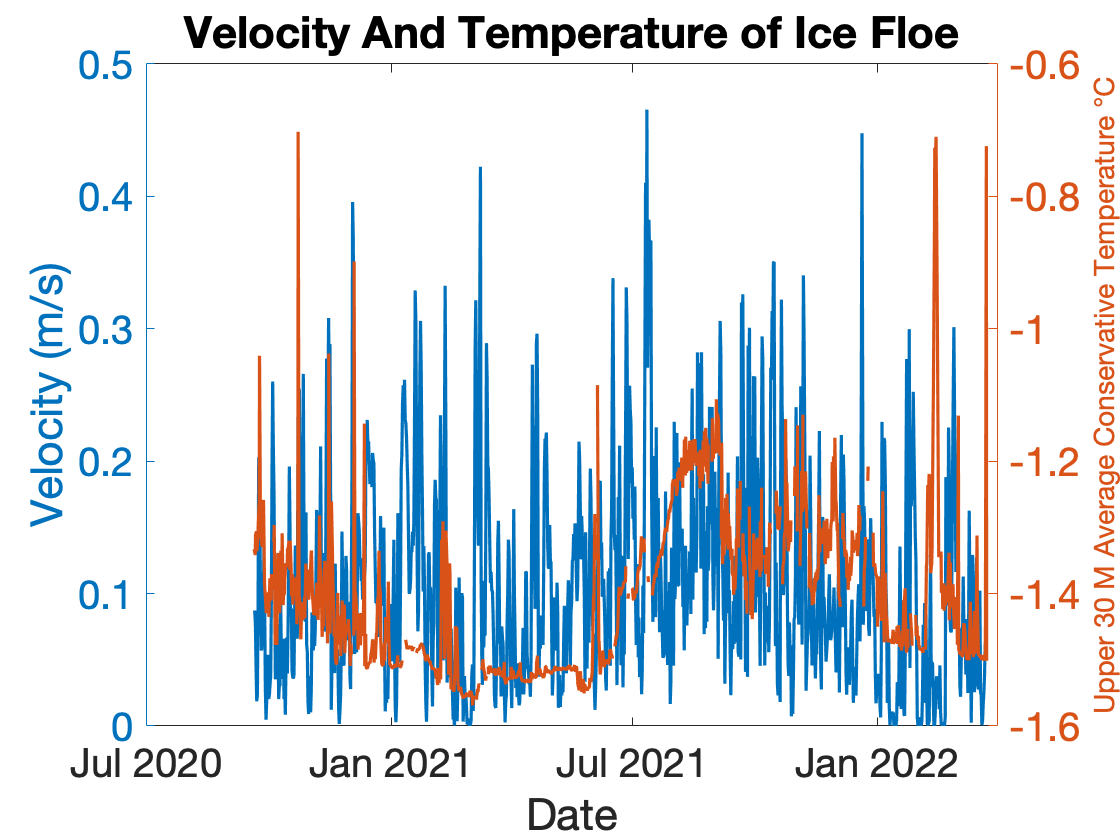

set(gca,'FontSize',20)
set(y,'FontSize',14)

save('IceSeaDrift','vel','time_midpoints','lat_midpoints1','lon_midpoints1','distance','time_diff_sec')
